# Demo for color detection

load('colorDetectionDemoData.mat');

## Visualize a sample image

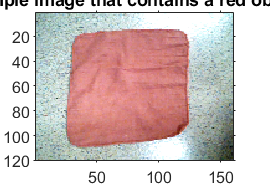

sampleImage = redCloth_1;
imshow(sampleImage);
title('Sample image that contains a red object');

## Segment out the red portion of the sample image

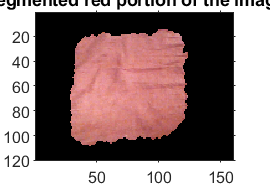

BW = false(size(sampleImage, 1), size(sampleImage, 2));

% red cloth
xPos = [41.3101 39.6468 38.9455 38.0000 37.0000 36.0000 35.1090 34.5974 34.4026 33.8910 33.1090 32.5974 32.5116 32.5429 32.7558 32.2442 32.4026 32.2442 32.1090 32.2442 32.4571 32.4884 32.4026 32.0000 31.7064 32.0000 32.3481 32.2442 31.3532 31.9455 32.3481 32.1897 31.7013 31.0545 30.7064 31.0545 31.6468 31.9455 31.2442 31.3481 31.0000 30.5974 30.4026 29.8910 29.1090 28.7064 29.0545 29.6468 28.7558 28.5974 28.7013 28.7013 28.6519 29.0545 29.5923 29.6468 29.2987 29.2987 29.6468 29.5923 29.0545 28.7064 29.1090 29.8910 30.3481 30.1897 29.8103 29.5429 29.4026 29.0000 28.7064 29.0000 29.4026 29.5429 29.7558 30.6468 30.0000 29.4077 29.3532 29.6468 29.6468 29.3532 29.4077 30.0545 30.9455 31.6468 31.9455 33.3532 34.0545 35.0000 36.0000 37.0000 38.0000 39.0000 39.9455 40.6468 42.3532 43.0545 44.0000 44.9455 45.6468 45.9455 47.3532 48.0545 48.9455 49.6468 51.3532 52.0545 53.0000 53.9455 54.6468 54.9455 56.3532 57.0545 58.0000 59.0000 60.0000 61.0000 62.0000 62.9455 63.6468 63.9455 65.3532 66.0000 66.7013 67.2987 68.0545 68.9455 69.6468 71.3532 72.0545 73.0000 74.0000 75.0000 76.0000 77.0000 78.0000 78.9455 79.6468 81.2987 81.7013 83.3532 84.0545 85.0000 85.9455 86.6468 88.3532 89.0545 90.0000 91.0000 91.9455 92.6468 94.3532 95.0545 96.0000 97.0000 97.9455 98.6468 100.3532 101.0545 102.0000 102.9455 103.6468 103.9455 105.3532 106.0545 107.0000 107.9455 108.6468 110.0545 110.3532 111.0000 111.6468 113.2987 113.7013 115.0000 115.0000 115.0000 116.3532 117.0545 117.9455 118.6468 120.3532 120.9455 121.3481 121.2442 121.9455 121.6468 121.0545 120.6519 120.7558 120.9455 122.0545 122.3532 122.9455 123.2936 122.8910 122.0545 121.4077 121.4077 122.0545 122.8910 123.3481 123.1897 122.7013 122.0000 121.3532 120.0545 120.3532 120.9455 121.3481 121.2442 122.2442 122.3481 121.9455 121.3532 121.6468 121.0000 120.4077 120.3532 120.7013 120.9455 121.6468 121.0000 120.3532 120.0545 119.9455 119.7558 119.6519 120.1090 120.8910 121.3481 121.2442 122.0545 122.3532 123.0000 123.6468 123.9455 123.9455 123.6468 123.0000 122.3532 121.6646 121.5127 121.0570 120.7532 120.2975 119.8418 119.6899 119.6899 119.6899 119.6899 119.6899 119.6899 119.8418 119.8418 119.8418 119.8418 119.8418 119.8418 119.8418 119.8418 119.8418 119.8418 119.8418 119.8418 119.9937 119.9937 121.2442 121.3481 120.8910 120.0545 119.2987 118.8103 118.5974 118.7558 117.9455 117.6468 116.9455 116.0000 115.0000 114.0000 113.0000 112.0000 111.0000 110.0545 109.3532 109.0545 107.6468 106.9455 106.0000 105.0000 104.0000 103.0000 102.0000 101.0000 100.0000 99.0000 98.0000 97.0000 96.0000 95.0000 94.0000 93.0000 92.0000 91.0000 90.0000 89.0000 88.0000 87.0000 86.0545 85.3532 83.6468 82.9455 82.0000 81.0000 80.0000 79.0000 78.0000 77.0545 76.3532 75.4873 74.8797 73.2089 71.8418 70.4747 69.5633 69.1076 68.1962 67.5886 67.1329 66.5253 66.2215 65.7658 65.1582 64.3987 63.7911 63.1835 62.7278 62.1203 61.6646 61.3608 61.3608 59.6468 58.9455 58.0000 57.0000 56.0000 55.0000 54.0000 53.0545 52.3532 50.6468 49.9455 49.0000 48.0000 47.0545 46.3532 44.6468 43.9455 43.0545 42.3532];
yPos = [19.7152 21.0545 21.3532 22.0545 23.0000 24.0000 25.0000 26.0000 27.0000 28.0000 29.0000 30.0000 31.0000 31.9455 32.6468 34.3532 35.0545 36.0000 37.0000 38.0000 39.0000 40.0000 41.0000 42.0000 43.0000 44.0000 44.9455 45.6468 47.3532 48.0545 49.0000 50.0000 51.0000 52.0000 53.0000 54.0000 54.9455 55.6468 57.3532 58.0545 59.0000 60.0000 61.0000 62.0000 63.0000 64.0000 64.9455 65.6468 67.3532 68.0545 69.0000 70.0000 71.0000 72.0000 73.0000 73.9455 74.6468 76.3532 77.0545 78.0000 79.0000 80.0000 81.0000 82.0000 83.0000 84.0000 85.0000 86.0000 87.0000 88.0000 89.0000 90.0000 90.9455 91.6468 91.9455 93.3532 94.0545 95.0000 96.0000 97.0000 98.0000 99.0000 100.0000 100.9455 101.7013 102.2442 102.7013 104.2442 104.4571 104.5974 105.1090 105.9455 106.7013 107.1897 107.4026 107.2442 107.3532 108.0000 108.5923 108.5923 108.0000 107.3532 107.9455 107.6468 107.0000 106.3532 104.7558 104.5974 104.7013 104.7013 104.5974 104.7558 105.6468 105.0545 104.7064 105.1090 105.8910 106.2936 106.0000 105.5974 105.4571 105.2442 105.6468 104.9455 104.0000 103.0545 102.4077 102.3532 102.7013 101.9455 101.7558 101.6519 102.1090 102.8910 103.3481 103.2987 103.3532 103.7013 103.9455 103.0000 103.0000 101.6468 101.0545 100.7064 101.0545 101.6468 102.6468 102.0545 101.5974 101.5116 101.5429 101.7558 103.2442 103.4026 103.1897 102.7013 102.0000 101.3532 102.2442 102.3481 101.8910 101.0000 100.0545 99.3532 100.0545 100.2442 100.3481 99.9455 99.3532 97.6468 97.0545 96.6519 96.7558 95.7013 95.2987 93.6468 93.0000 92.3532 90.9455 90.6468 90.0000 89.3532 87.6468 87.0000 86.3532 86.0545 84.6468 83.9455 83.0000 82.0000 81.0545 80.3532 78.6468 77.9455 77.0000 76.0000 75.0000 74.0000 73.0000 72.0000 71.0000 70.0000 69.0000 68.0000 67.0000 66.0545 65.3532 63.6468 62.9455 62.0000 61.0545 60.3532 58.6468 58.0000 57.3532 57.0545 55.6468 54.9455 54.0000 53.0000 52.0545 51.3532 49.6468 48.9455 48.0545 47.3532 45.6468 44.9455 44.0000 43.0000 42.0000 41.0545 40.3532 38.6468 37.9455 37.0000 36.0000 35.0000 34.0000 33.1090 32.6519 32.7558 32.9304 32.9304 33.2342 33.5380 33.6899 33.8418 34.1456 34.6013 34.7532 34.9051 35.2089 35.0570 34.9051 34.2975 33.6899 33.0823 32.4747 32.0190 31.5633 31.1076 30.9557 30.5000 30.3481 30.1962 30.0443 29.4367 27.6468 26.9455 26.0000 25.0000 24.0000 23.0000 22.0545 21.3532 19.6468 19.0000 18.2987 17.8103 17.5974 17.7013 17.5923 16.9455 16.0545 15.4077 15.3532 15.7013 14.9455 14.7013 14.3532 14.2987 14.4571 14.4884 14.5116 14.5429 14.8103 15.2987 16.0545 17.0000 17.9455 18.7013 19.1897 19.4026 19.1897 18.7558 18.2442 17.8103 17.5429 17.5116 17.5429 17.7558 18.9455 18.6468 18.0545 17.6519 17.7013 17.7013 17.6519 18.0545 18.6468 18.5000 18.6519 18.8038 18.9557 18.9557 19.1076 19.1076 19.1076 19.1076 19.1076 19.1076 19.1076 19.1076 19.1076 19.1076 19.1076 19.1076 19.1076 19.1076 19.1076 19.1076 18.9557 17.7558 17.5429 17.4026 17.0000 16.6519 16.8103 17.2987 18.0000 18.6468 20.2442 20.3481 19.8910 19.1090 18.6519 18.7558 20.0545 20.2442 20.4026 20.2442];

m = size(BW, 1);
n = size(BW, 2);
addedRegion = poly2mask(xPos, yPos, m, n);
BW = BW | addedRegion;

segmentedImage = sampleImage;
segmentedImage(repmat(~ BW, [1, 1, 3])) = 0;
imshow(segmentedImage);
title('Segmented red portion of the image');

## Calculate the typical R, G, and B values

segmentedImage = double(segmentedImage);
for i = 1 : size(segmentedImage, 1)
    for j = 1 : size(segmentedImage, 2)
        if segmentedImage(i, j, 1) == 0 && segmentedImage(i, j, 2) == 0 && segmentedImage(i, j, 3) == 0
            segmentedImage(i, j, :) = NaN;
        end
    end
end

typicalR = mean(segmentedImage(:, :, 1), 'all', 'omitnan')

typicalR = 209.0842

typicalG = mean(segmentedImage(:, :, 2), 'all', 'omitnan')

typicalG = 126.4433

typicalB = mean(segmentedImage(:, :, 3), 'all', 'omitnan')

typicalB = 124.0513

## Compare between a typical red image and a typical nonred image

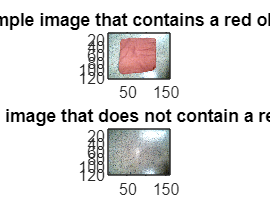

distances = zeros(size(sampleImage, 1 : 2));
redPixels = zeros(size(sampleImage, 1 : 2));
distanceThreshold = 80;
for i = 1 : size(sampleImage, 1)
    for j = 1 : size(sampleImage, 2)
        distances(i, j) = redmeanDistance(sampleImage(i, j, 1), sampleImage(i, j, 2), sampleImage(i, j, 3), typicalR, typicalG, typicalB);
        redPixels(i, j) = distances(i, j) < distanceThreshold;
    end
end
sampleImageWithRedPixels = sampleImage .* uint8(redPixels);

distancesNonred = zeros(size(sampleNonredImage, 1 : 2));
for i = 1 : size(sampleNonredImage, 1)
    for j = 1 : size(sampleNonredImage, 2)
        distancesNonred(i, j) = redmeanDistance(sampleNonredImage(i, j, 1), sampleNonredImage(i, j, 2), sampleNonredImage(i, j, 3), typicalR, typicalG, typicalB);
    end
end

figure;
subplot(2, 1, 1);
imshow(sampleImage);
title('Sample image that contains a red object');
subplot(2, 1, 2);
histogram(distances);
imshow(sampleNonredImage);
title('Sample image that does not contain a red object');

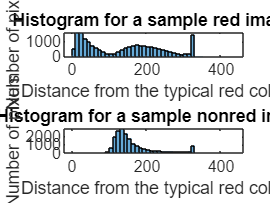


figure;
subplot(2, 1, 1);
histogram(distances, 0 : 10 : 440);
xlabel('Distance from the typical red color');
ylabel('Number of pixels');
title('Histogram for a sample red image');
subplot(2, 1, 2);
histogram(distancesNonred, 0 : 10 : 440);
xlabel('Distance from the typical red color');
ylabel('Number of pixels');
title('Histogram for a sample nonred image');

## Compare between visually segmented and distance-based segmented images

numOfRedPixelsInVisuallySegmentedImage = sum(~ isnan(segmentedImage(:, :, 1)), 'all')

numOfRedPixelsInVisuallySegmentedImage = 7569

numOfRedPixelsInDistanceBasedSegmentedImage = sum(distances < distanceThreshold, 'all')

numOfRedPixelsInDistanceBasedSegmentedImage = 7585

## Visualize the red pixels in the sample image

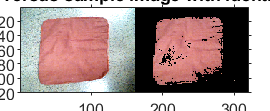

figure;
imshowpair(sampleImage, sampleImageWithRedPixels, 'montage');
title('Sample image versus sample image with identified red pixels');

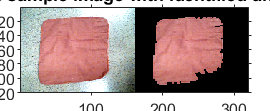


adjustedRedPixels = imfill(imopen(imclose(redPixels, strel('square', 2)), strel('square', 3)), 'holes');
sampleImageWithAdjustedRedPixels = sampleImage .* uint8(adjustedRedPixels);

figure;
imshowpair(sampleImage, sampleImageWithAdjustedRedPixels, 'montage');
title('Sample image versus sample image with identified and adjusted red pixels');

## Visualize the colors that are classified as red by our algorithm

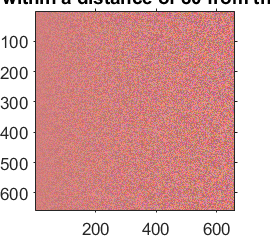

% red cloth
typicalR = 209.0842;
typicalG = 126.4433;
typicalB = 124.0531;

% red plate (alternative reference color)
altR_1 = 133.4823;
altG_1 = 49.4894;
altB_1 = 45.6421;

% five colors (another alternative reference color)
altR_2 = 217.0304;
altG_2 = 71.0106;
altB_2 = 69.4320;

allColors = uint8(zeros(1, 256 ^ 3, 3));
for i = 0 : 255
    for j = 0 : 255
        for k = 0 : 255
            allColors(1, 256 ^ 2 * i + 256 * j + (k + 1), :) = [i, j, k];
        end
    end
end

distances = zeros(size(allColors, 1 : 2));
distances_alt_1 = zeros(size(allColors, 1 : 2));
distances_alt_2 = zeros(size(allColors, 1 : 2));
for j = 1 : size(allColors, 2)

    distances(1, j) = redmeanDistance(allColors(1, j, 1), allColors(1, j, 2), allColors(1, j, 3), typicalR, typicalG, typicalB);
    distances_alt_1(1, j) = redmeanDistance(allColors(1, j, 1), allColors(1, j, 2), allColors(1, j, 3), altR_1, altG_1, altB_1);
    distances_alt_2(1, j) = redmeanDistance(allColors(1, j, 1), allColors(1, j, 2), allColors(1, j, 3), altR_2, altG_2, altB_2);    

end

distancesBelowThreshold = distances(distances < distanceThreshold);
[~, sortingIndices] = sort(distancesBelowThreshold);
distancesBelowThreshold_alt_1 = distances_alt_1(distances_alt_1 < distanceThreshold);
[~, sortingIndices_alt_1] = sort(distancesBelowThreshold_alt_1);
distancesBelowThreshold_alt_2 = distances_alt_2(distances_alt_2 < distanceThreshold);
[~, sortingIndices_alt_2] = sort(distancesBelowThreshold_alt_2);

redColors = allColors(1, distances < distanceThreshold, :);
redColorsSorted = redColors(1, sortingIndices, :);
redColors_alt_1 = allColors(1, distances_alt_1 < distanceThreshold, :);
redColorsSorted_alt_1 = redColors_alt_1(1, sortingIndices_alt_1, :);
redColors_alt_2 = allColors(1, distances_alt_2 < distanceThreshold, :);
redColorsSorted_alt_2 = redColors_alt_2(1, sortingIndices_alt_2, :);

redColorsSortedZeroPadded = padarray(redColorsSorted, [0, ceil(sqrt(size(redColorsSorted, 2))) ^ 2 - size(redColorsSorted, 2)], 'post');
redColorsSortedZeroPaddedReshaped = reshape(redColorsSortedZeroPadded, sqrt(size(redColorsSortedZeroPadded, 2)), sqrt(size(redColorsSortedZeroPadded, 2)), 3);
redColorsSortedZeroPadded_alt_1 = padarray(redColorsSorted_alt_1, [0, ceil(sqrt(size(redColorsSorted_alt_1, 2))) ^ 2 - size(redColorsSorted_alt_1, 2)], 'post');
redColorsSortedZeroPaddedReshaped_alt_1 = reshape(redColorsSortedZeroPadded_alt_1, sqrt(size(redColorsSortedZeroPadded_alt_1, 2)), sqrt(size(redColorsSortedZeroPadded_alt_1, 2)), 3);
redColorsSortedZeroPadded_alt_2 = padarray(redColorsSorted_alt_2, [0, ceil(sqrt(size(redColorsSorted_alt_2, 2))) ^ 2 - size(redColorsSorted_alt_2, 2)], 'post');
redColorsSortedZeroPaddedReshaped_alt_2 = reshape(redColorsSortedZeroPadded_alt_2, sqrt(size(redColorsSortedZeroPadded_alt_2, 2)), sqrt(size(redColorsSortedZeroPadded_alt_2, 2)), 3);

figure;
imshow(redColorsSortedZeroPaddedReshaped);
title('All colors that are within a distance of 80 from the typical red color');

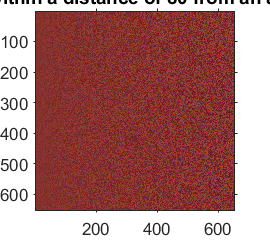

imshow(redColorsSortedZeroPaddedReshaped_alt_1);
title('All colors that are within a distance of 80 from an alternative red color');

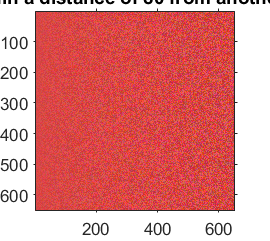

imshow(redColorsSortedZeroPaddedReshaped_alt_2);
title('All colors that are within a distance of 80 from another alternative red color');

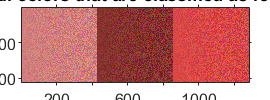


montage({redColorsSortedZeroPaddedReshaped, redColorsSortedZeroPaddedReshaped_alt_1, redColorsSortedZeroPaddedReshaped_alt_2}, 'Size', [1, 3]);
title('All colors that are classified as red');

## Demonstrate the performance on a variety of data

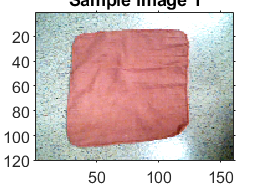

imshow(redCloth_1);
title('Sample image 1');

[redPixels, containsRed] = containsRedObject(redCloth_1(:, :, 1), redCloth_1(:, :, 2), redCloth_1(:, :, 3));
containsRed

containsRed = logical
   1


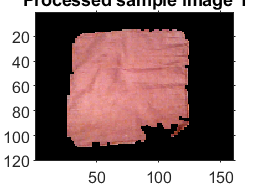

imshow(redPixels);
title('Processed sample image 1');

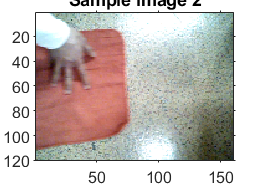


imshow(redCloth_2);
title('Sample image 2');

[redPixels, containsRed] = containsRedObject(redCloth_2(:, :, 1), redCloth_2(:, :, 2), redCloth_2(:, :, 3));
containsRed

containsRed = logical
   1


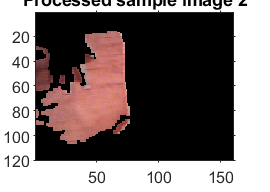

imshow(redPixels);
title('Processed sample image 2');

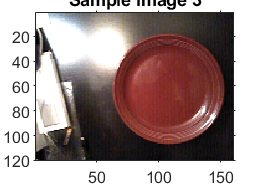


imshow(redPlate_1);
title('Sample image 3');

[redPixels, containsRed] = containsRedObject(redPlate_1(:, :, 1), redPlate_1(:, :, 2), redPlate_1(:, :, 3));
containsRed

containsRed = logical
   1


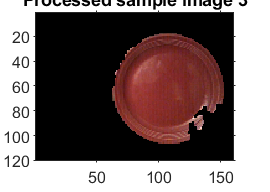

imshow(redPixels);
title('Processed sample image 3');

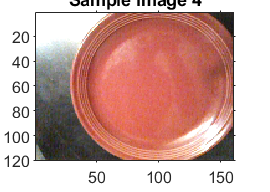


imshow(redPlate_2);
title('Sample image 4');

[redPixels, containsRed] = containsRedObject(redPlate_2(:, :, 1), redPlate_2(:, :, 2), redPlate_2(:, :, 3));
containsRed

containsRed = logical
   1


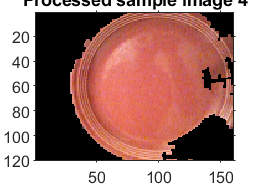

imshow(redPixels);
title('Processed sample image 4');

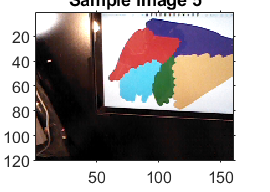


imshow(fiveColors_1);
title('Sample image 5');

[redPixels, containsRed] = containsRedObject(fiveColors_1(:, :, 1), fiveColors_1(:, :, 2), fiveColors_1(:, :, 3));
containsRed

containsRed = logical
   1


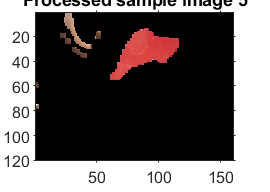

imshow(redPixels);
title('Processed sample image 5');

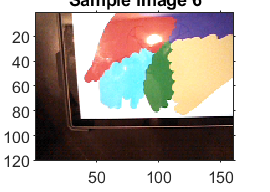


imshow(fiveColors_2);
title('Sample image 6');

[redPixels, containsRed] = containsRedObject(fiveColors_2(:, :, 1), fiveColors_2(:, :, 2), fiveColors_2(:, :, 3));
containsRed

containsRed = logical
   1


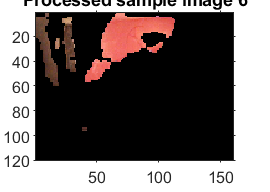

imshow(redPixels);
title('Processed sample image 6');

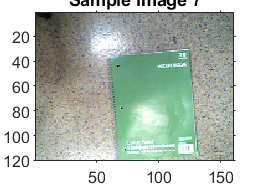


imshow(greenNotebook);
title('Sample image 7');

[redPixels, containsRed] = containsRedObject(greenNotebook(:, :, 1), greenNotebook(:, :, 2), greenNotebook(:, :, 3));
containsRed

containsRed = logical
   0


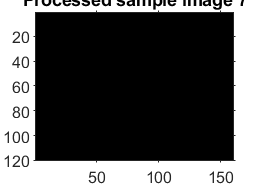

imshow(redPixels);
title('Processed sample image 7');

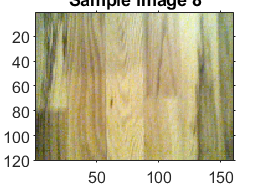


imshow(floor);
title('Sample image 8');

[redPixels, containsRed] = containsRedObject(floor(:, :, 1), floor(:, :, 2), floor(:, :, 3));
containsRed

containsRed = logical
   0


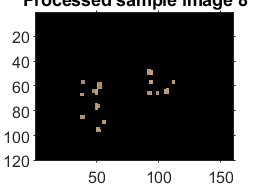

imshow(redPixels);
title('Processed sample image 8');

function [redPixels, containsRed] = containsRedObject(R, G, B) % the new algorithm ("distance comparison")

    % input: three 120x160 uint8 arrays R, G, and B
    % output: a 120x160x3 uint8 array redPixels indicating where the red pixels are in the input image
    %         and a boolean value isRed representing whether there is a significant presence of a
    %         red object in the input image represented by R, G, and B

    RGB = cat(3, R, G, B);

    distanceThreshold = 80;
    areaThreshold =  0.05 * size(RGB, 1) * size(RGB, 2); % 960 (5% of the total image area)

    % red cloth
    typicalR = 209.0842;
    typicalG = 126.4433;
    typicalB = 124.0531;
    
    % red plate (alternative reference color)
    altR_1 = 133.4823;
    altG_1 = 49.4894;
    altB_1 = 45.6421;
    
    % five colors (another alternative reference color)
    altR_2 = 217.0304;
    altG_2 = 71.0106;
    altB_2 = 69.4320;

    distances = zeros(size(RGB, 1 : 2));
    distances_alt_1 = zeros(size(RGB, 1 : 2));
    distances_alt_2 = zeros(size(RGB, 1 : 2));
    redPixels_logical = false(size(RGB, 1 : 2));

    for i = 1 : size(RGB, 1)
        for j = 1 : size(RGB, 2)

            distances(i, j) = redmeanDistance(RGB(i, j, 1), RGB(i, j, 2), RGB(i, j, 3), typicalR, typicalG, typicalB);
            distances_alt_1(i, j) = redmeanDistance(RGB(i, j, 1), RGB(i, j, 2), RGB(i, j, 3), altR_1, altG_1, altB_1);
            distances_alt_2(i, j) = redmeanDistance(RGB(i, j, 1), RGB(i, j, 2), RGB(i, j, 3), altR_2, altG_2, altB_2);

            redPixels_logical(i, j) = (distances(i, j) < distanceThreshold) | (distances_alt_1(i, j) < distanceThreshold) ...
                                    | (distances_alt_2(i, j) < distanceThreshold); % determine the "red status" of each pixel
        
        end
    end

    redPixels_logical = imfill(imopen(imclose(redPixels_logical, strel('square', 2)), strel('square', 3)), 'holes');
    redPixels = RGB .* uint8((redPixels_logical == 1));

    % if the number of red pixels is greater than the area threshold, then the image is classified as red
    containsRed = sum(redPixels_logical, 'all') > areaThreshold;

end

function distance = redmeanDistance(R, G, B, R_ref, G_ref, B_ref)

    deltaR = double(R) - double(R_ref);
    deltaG = double(G) - double(G_ref);
    deltaB = double(B) - double(B_ref);
    r_bar = (1 / 2) * (double(R) + double(R_ref));

    distance = sqrt((2 + r_bar / 256) * deltaR ^ 2 + 4 * deltaG ^ 2 + (2 + (255 - r_bar) / 256) * deltaB ^ 2);

end